# Figure 4 of Kairzhan, Pelinovsky, Goodman without PML

A simulation of the solution to NLS on the "balanced" star graph studied in 

Kairzhan, A., Pelinovsky, D. E., & Goodman, R. H. (2019). *Drift of Spectrally Stable Shifted States on Star Graphs*. **SIAM Journal on Applied Dynamical Systems**, 18(4), 1723–1755. 

This simulation is the same ast in KPT_Figure4, except that instead of using the perfectly matched layer to absorb radiation, we simply apply Dirichlet boundary conditions at the three leaf nodes.

## Set up the quantum graph

nEdges = 3;
Lphysical = 16;
LPML = 2;
L = Lphysical + LPML;
nx = 20;
weight=[2 1 1];   % This defines a Balance star graph as defined in the paper
robinCoeff = [0 nan nan nan]; % specify weighted Kirchhoff BCs at vertex, Dirichlet BCs at leaf nodes
Phi = quantumGraphFromTemplate('star','n',nEdges,'LVec',L,'nx',nx,'weight',weight,'robinCoeff',robinCoeff);

## Set up the initial condition

The initial condition consists of the shifted state, with a small perturbation in the direction of the eigenfunction. This breaks the symmetry between the solution on edges 2 & 3. The maximum is initially on edge 1, the "incoming" edge. Such solutions are shown in the paper to be linearly stable but nonlinearly unstable. The solution very slowly drifts until it reaches $x=0$, after which it picks up momentum and escapes along edge 3.

x0 = 0.55;
v0 = 0;
epsilon = 0.1; 
Phi0vector=shiftedState(Phi,x0,v0);
perturbationVector=firstLPlusEigenfunction(Phi,x0);
u0 = Phi0vector+epsilon*perturbationVector;

## Solve the PDE

A = Phi.laplacianMatrix;
tfinal = 45; dt = 0.005; tplot = .1;
U=solveWeidemannHerbst(A,u0,tfinal,dt,tplot);

## Plot the solution as a space-time false color plot on each edge

This is the image plotted in Figure 3.

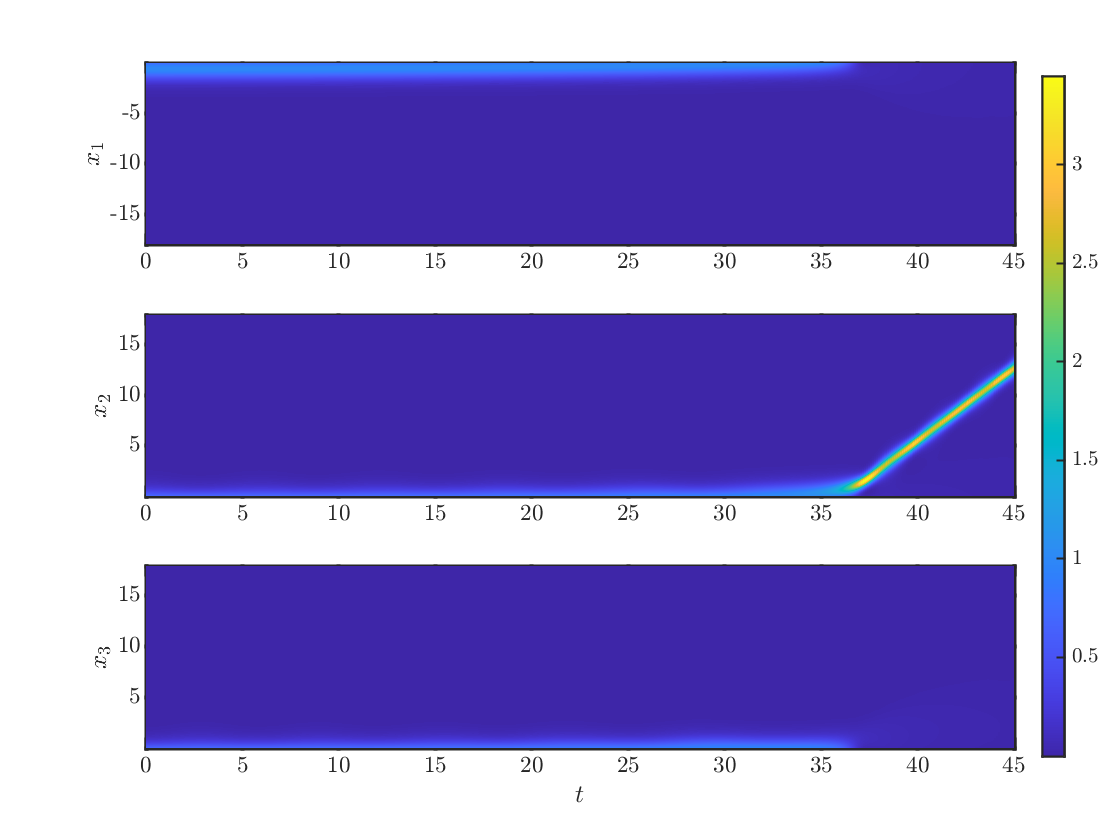

nt=size(U,2);t=tplot*(0:nt-1)';
pcolorPDESolution(U,Phi,t)

## 3D animation of the solution

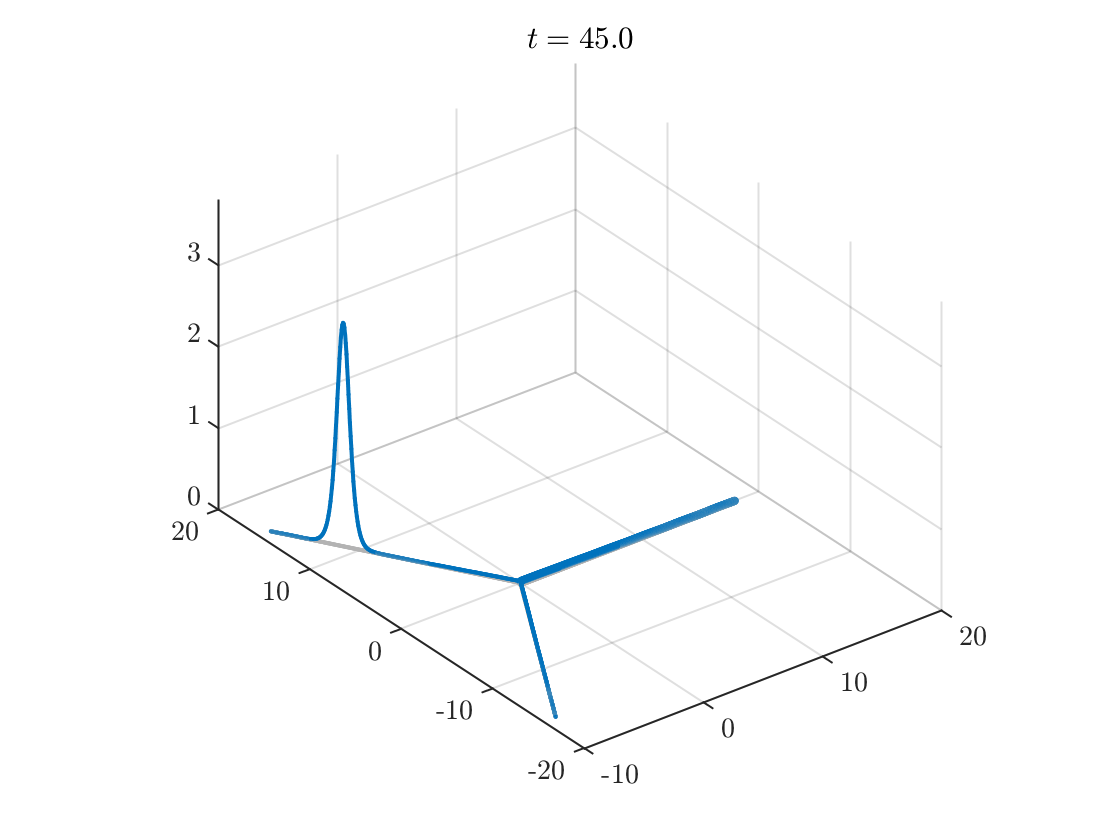

Phi.animatePDESolution(U,t)

## 2D animation of the solution

From this plot it's easier to see the growth of the asymmetry of the solution, initially perturbed so that the norm on edge 2 is larger than on edge 3. Note that as long as the solution maximum is on edge 1, then a small amount of energy oscillates between edge 2 and edge 3.

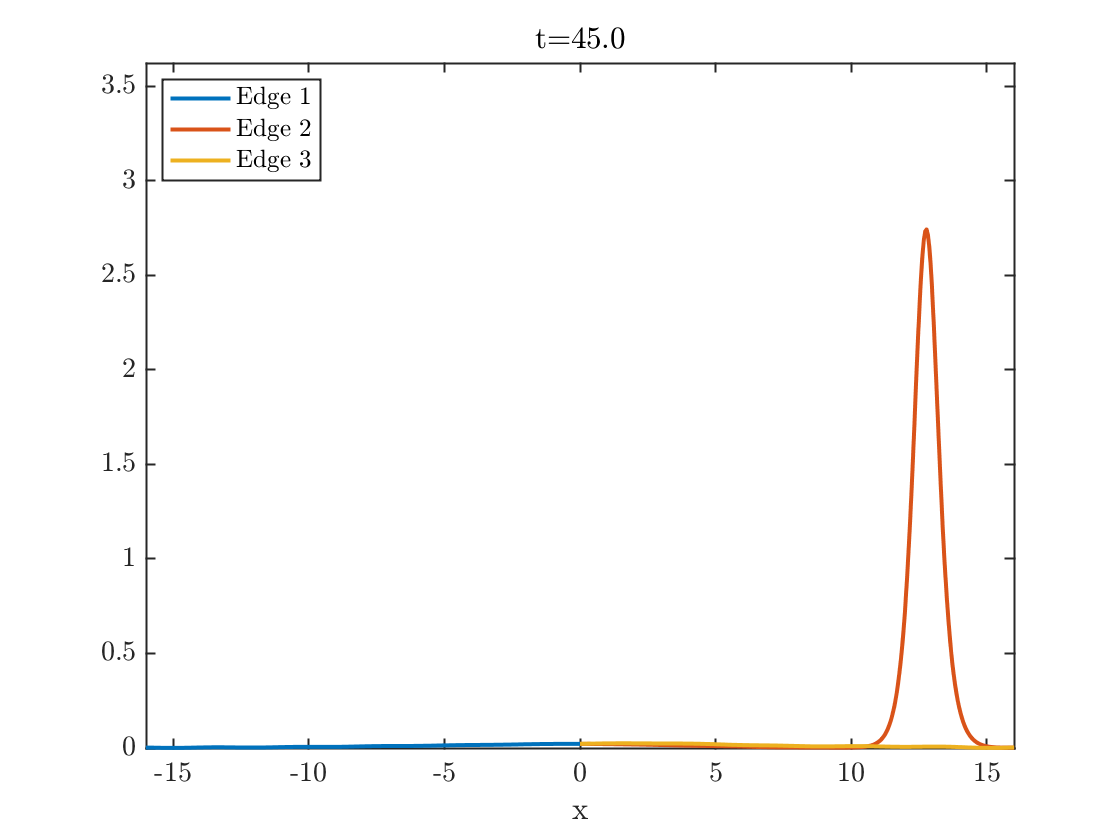

animatePDESolution2D(U,Phi,t,PMLparams.d);

## Visualization of the asymmetry between edges 2 and 3

Plotting $|| u_2|| - ||u_3||$. Oscillation between the two edges clearly visible.

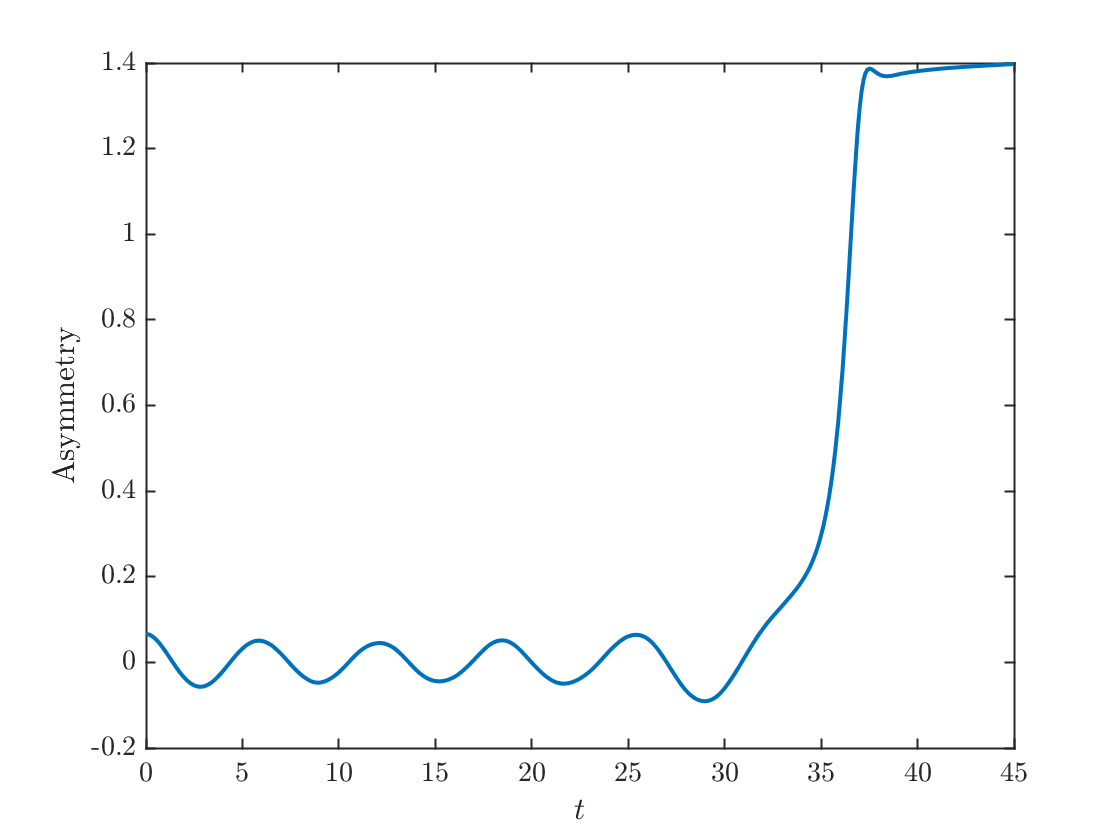

asymmetry=zeros(nt,1);
for k=1:nt
    Phi.column2graph(U(:,k));
    asymmetry(k)=getL2Asymmetry(Phi);
end
plot(t,asymmetry);
xlabel('$t$'); ylabel('Asymmetry')

## Plot the location of the maximum of the solution

The color tells you which brianch the solution is on. We see that the solution is initially concentrated on edge 1, before leaving along edge 3.

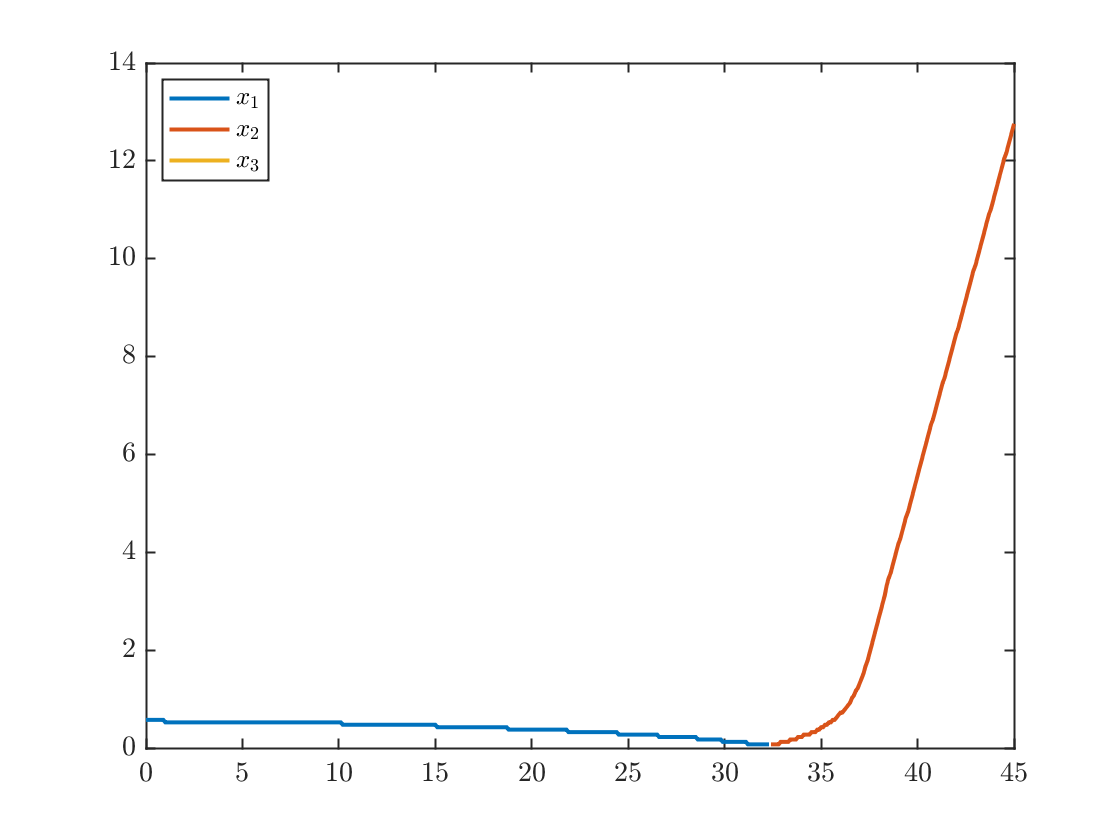

branch=zeros(nt,1);
xmax=zeros(nt,1);

for k=1:nt
    Phi.column2graph(U(:,k));
    asymmetry(k)=getL2Asymmetry(Phi);
    [branch(k),xmax(k)]=locateStarMax(U(:,k),Phi);
end
 x1=xmax;x1(branch~=1)=nan;
 x2=xmax;x2(branch~=2)=nan;
 x3=xmax;x3(branch~=3)=nan;
 plot(t,x1,t,x2,t,x3);legend('$x_1$','$x_2$','$x_3$','Location','northwest')

## Plot the conserved quantities

The Energy and L2 norm are not conserved exactly due to damping in the perfectly matched layers. The momentum is strictly increasing, going from zero to a constant of about 2.

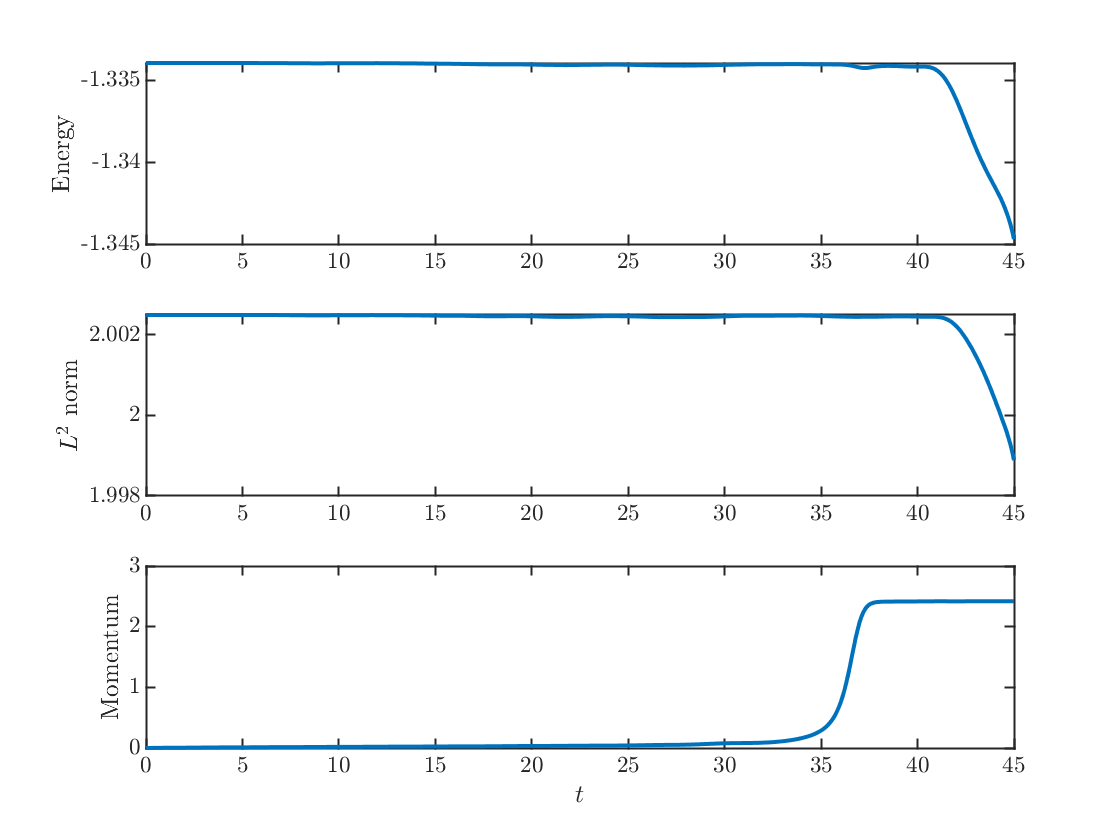

mVec=ones(nEdges,1);mVec(1)=-1; % m-vector, used for computing momentum only
Phi.qg.Edges.m=mVec;
[P,E,L2]=getAllConservedPML(U,Phi,PMLparams.d);
subplot(3,1,1)
plot(t,E)
ylabel('Energy')
subplot(3,1,2)
plot(t,L2)
ylabel('$L^2$ norm')
subplot(3,1,3)
plot(t,P)
xlabel('$t$')
ylabel('Momentum')

fprintf('Relative change in Energy: %0.2f%%\n',100*(max(E)-min(E))/max(E))

Relative change in Energy: -0.81%


fprintf('Relative change in L2-norm: %0.2f%%\n',100*(max(L2)-min(L2))/max(L2))

Relative change in L2-norm: 0.18%


fprintf('Relative change in Momentum: %0.2f%%\n',100*(max(P)-min(P))/max(P))

Relative change in Momentum: 100.00%
